%% 
%exercise 2% 
%Exercise 2
%Let's say you know that a given nerve terminal contains exactly 14 quanta available for release.
% You have read in the literature that the release probability of these quanta is low, say 0.1. 
% To assess whether this value is reasonable, you run a simple experiment: activate the 
% nerve and measure the number of quanta that are released. The result is 8 quanta. 
% What is the probability that you would get this result (8 quanta) 
% if the true probability of release really was 0.1? What about if the true 
% release probability was much higher; say, 0.7? 
% What about for each decile of release probability (0.1, 0.2, ... 1.0)? 
% Which value of release probability did you determine to be the most probable, given your measurement?

%Note: here you are computing a likelihood function: a function describing how the value of the 
% conditional probability p(data | parameters) changes when you hold your data fixed to the value(s)
% you measured and vary the value(s) of the parameter(s) of, in this case, the binomial distribution. 
% Because you are varying the parameters and not the data, the values of the function are not expected 
% to sum to one (e.g., you can have numerous parameters that have a very high probability of producing 
% the given data) and thus this function is not a probability distribution (see here for an extended discussion). 
% The maximum value of this function is called the maximum likelihood.




%Answer: 0 probability when p = 0.1


p = .1

p = 0.1000

n = 14

n = 14

num_experiments = 1

num_experiments = 1

outcomes = binornd(n,p, num_experiments, 1)

outcomes = 2

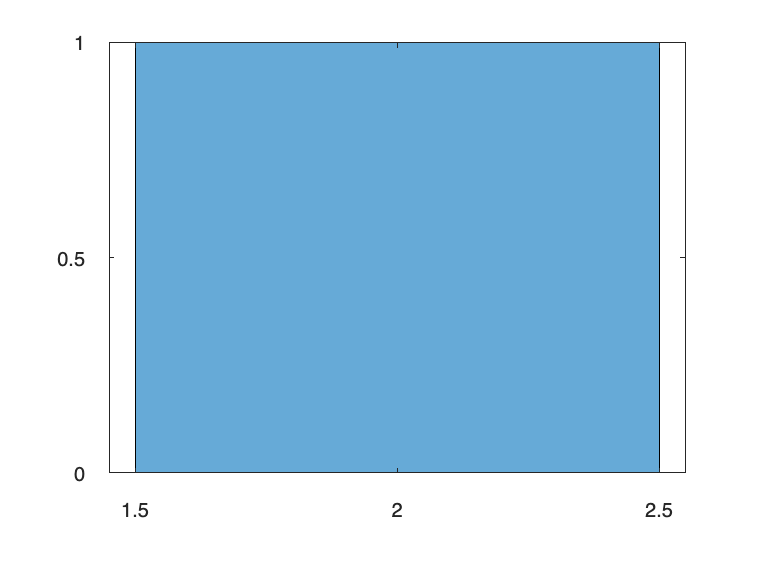

histogram(outcomes)


edges = -0.5:10.5;
counts = histcounts(outcomes, edges);
xAxis = edges(1:end-1)+diff(edges)/2;


bar(xAxis, counts./sum(counts))
hold on
xlabel(sprintf('PDF of binominal distribution, n=%d, p=%.2f, N=%d stimulations', n, p, num_experiments))
ylabel("probability")

y = binopdf(xAxis, n, p)

y =     0.2288    0.3559    0.2570    0.1142    0.0349    0.0078    0.0013    0.0002    0.0000    0.0000    0.0000


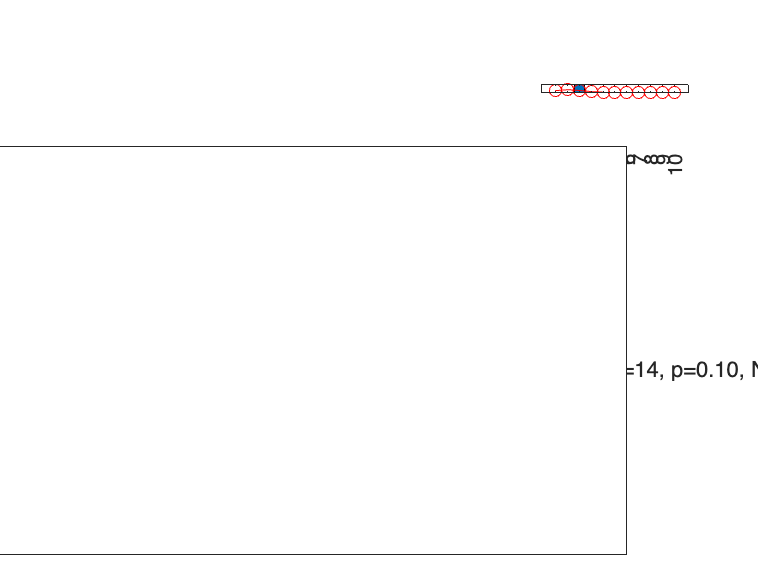

hold on 
plot(xAxis,y,'ro-')
legend('Simulated','theoretical')
hold off

%when p = .7, high probability of 8 quanta release
p = .7

p = 0.7000

n = 14

n = 14

num_experiments = 1

num_experiments = 1

outcomes = binornd(n,p, num_experiments, 1)

outcomes = 10

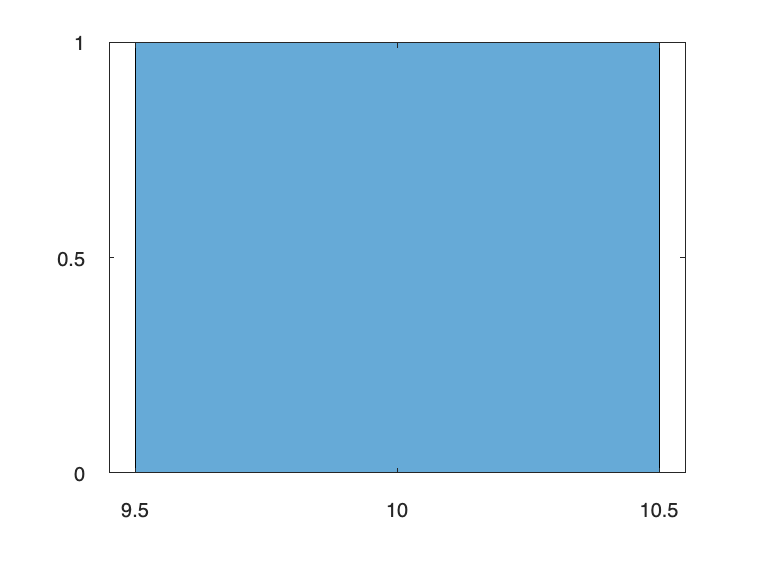

histogram(outcomes)


edges = -0.5:10.5;
counts = histcounts(outcomes, edges);
xAxis = edges(1:end-1)+diff(edges)/2;


bar(xAxis, counts./sum(counts));
hold on
xlabel(sprintf('PDF of binominal distribution, n=%d, p=%.2f, N=%d stimulations', n, p, num_experiments))
ylabel("probability")

y = binopdf(xAxis, n, p)

y =     0.0000    0.0000    0.0000    0.0002    0.0014    0.0066    0.0232    0.0618    0.1262    0.1963    0.2290


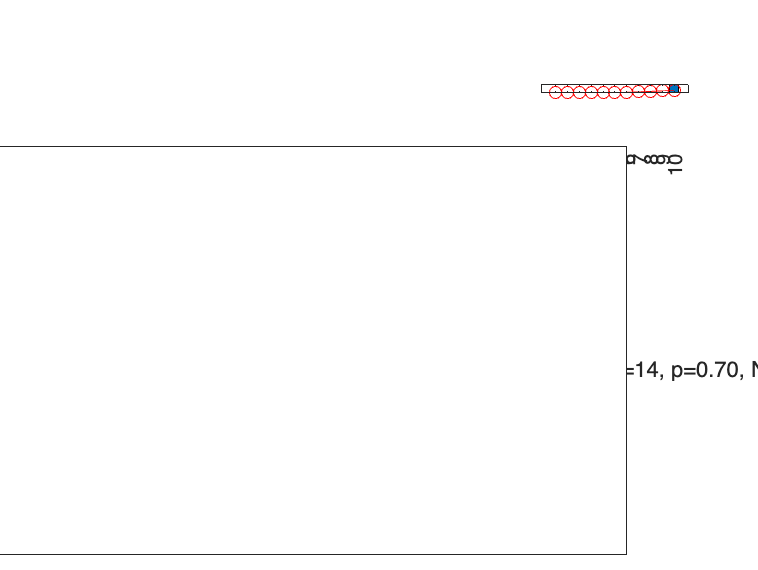


plot(xAxis,y,'ro-')
legend('Simulated','theoretical')
hold off

%Number of quanta most likely to be released for a given release
%probability.
probability_range = [0.1:0.1:1.0]

probability_range =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


for p = probability_range
    n = 14;
    num_experiments = 1;
    outcomes = binornd(n,p, num_experiments, 1);
    sprintf('Number of quanta likely to be released when release probability = %.2f: %d ', p, outcomes)

end

ans = 'Number of quanta likely to be released when release probability = 0.10: 1 Number of quanta likely to be released when release probability = 1.00: 1 Number of quanta likely to be released when release probability = 0.00: 1 Number of quanta likely to be released when release probability = 1.00: 0 Number of quanta likely to be released when release probability = 0.00: 1 Number of quanta likely to be released when release probability = 2.00: '

ans = 'Number of quanta likely to be released when release probability = 0.20: 2 Number of quanta likely to be released when release probability = 4.00: 3 Number of quanta likely to be released when release probability = 6.00: 4 Number of quanta likely to be released when release probability = 3.00: 2 Number of quanta likely to be released when release probability = 1.00: 1 Number of quanta likely to be released when release probability = 3.00: '

ans = 'Number of quanta likely to be released when release probability = 0.30: 5 Number of quanta likely to be released when release probability = 6.00: 3 Number of quanta likely to be released when release probability = 4.00: 2 Number of quanta likely to be released when release probability = 5.00: 3 Number of quanta likely to be released when release probability = 7.00: 5 Number of quanta likely to be released when release probability = 8.00: '

ans = 'Number of quanta likely to be released when release probability = 0.40: 5 Number of quanta likely to be released when release probability = 7.00: 5 Number of quanta likely to be released when release probability = 6.00: 6 Number of quanta likely to be released when release probability = 2.00: 6 Number of quanta likely to be released when release probability = 5.00: 6 Number of quanta likely to be released when release probability = 2.00: '

ans = 'Number of quanta likely to be released when release probability = 0.50: 6 Number of quanta likely to be released when release probability = 8.00: 7 Number of quanta likely to be released when release probability = 7.00: 7 Number of quanta likely to be released when release probability = 7.00: 7 Number of quanta likely to be released when release probability = 5.00: 6 Number of quanta likely to be released when release probability = 6.00: '

ans = 'Number of quanta likely to be released when release probability = 0.60: 10 Number of quanta likely to be released when release probability = 7.00: 9 Number of quanta likely to be released when release probability = 4.00: 9 Number of quanta likely to be released when release probability = 12.00: 12 Number of quanta likely to be released when release probability = 9.00: 8 Number of quanta likely to be released when release probability = 5.00: '

ans = 'Number of quanta likely to be released when release probability = 0.70: 9 Number of quanta likely to be released when release probability = 11.00: 7 Number of quanta likely to be released when release probability = 9.00: 11 Number of quanta likely to be released when release probability = 9.00: 11 Number of quanta likely to be released when release probability = 8.00: 12 Number of quanta likely to be released when release probability = 8.00: '

ans = 'Number of quanta likely to be released when release probability = 0.80: 11 Number of quanta likely to be released when release probability = 10.00: 11 Number of quanta likely to be released when release probability = 11.00: 12 Number of quanta likely to be released when release probability = 11.00: 12 Number of quanta likely to be released when release probability = 9.00: 11 Number of quanta likely to be released when release probability = 10.00: '

ans = 'Number of quanta likely to be released when release probability = 0.90: 11 Number of quanta likely to be released when release probability = 14.00: 14 Number of quanta likely to be released when release probability = 14.00: 12 Number of quanta likely to be released when release probability = 13.00: 12 Number of quanta likely to be released when release probability = 11.00: 12 Number of quanta likely to be released when release probability = 13.00: '

ans = 'Number of quanta likely to be released when release probability = 1.00: 14 Number of quanta likely to be released when release probability = 14.00: 14 Number of quanta likely to be released when release probability = 14.00: 14 Number of quanta likely to be released when release probability = 14.00: 14 Number of quanta likely to be released when release probability = 14.00: 14 Number of quanta likely to be released when release probability = 14.00: '